%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TUE 5SMB0 System Identification
%%% Assignment 2022
%%% Authors: Jiaxuan Zhang, Yiting Li
%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Data Generation

% [ u , y ] = assignment_sys_36(r)
clear all
close all 
clc


## Part 1: Understanding Saturation and Butterworth Filter

### 1.1

F.num = [ 0.505 , 1.01 , 0.505 ];
F.denom = [ 1 , 0.7478 , 0.2722 ];
F.sys = tf(F.num, F.denom, -1, 'Variable', 'z^-1')

F = struct with fields:
      num: [0.5050 1.0100 0.5050]
    denom: [1 0.7478 0.2722]
      sys: [1×1 tf]


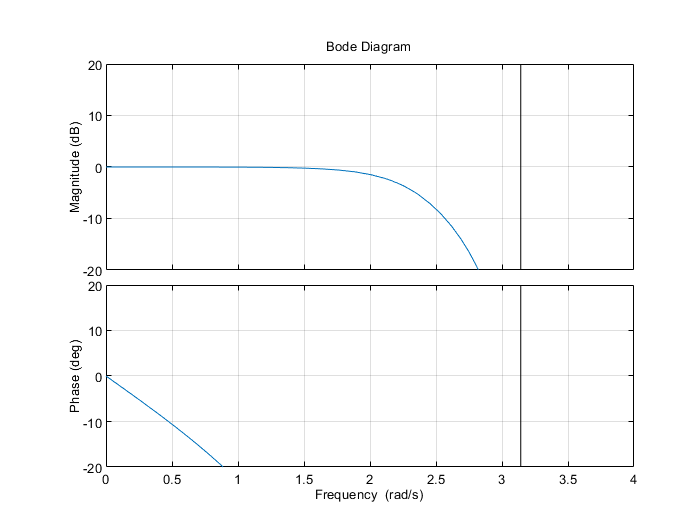


plotopts1 = bodeoptions;
plotopts1.FreqScale = 'linear';
plotopts1.XLim = {[0,4]};
plotopts1. Ylim = {[-20,20]};
plotopts1.Grid = 'on';
bode(F.sys, plotopts1)

% w = 2.1954 rad/s is the -3 db point, f = w/2/pi = 0.3494


### 1.2

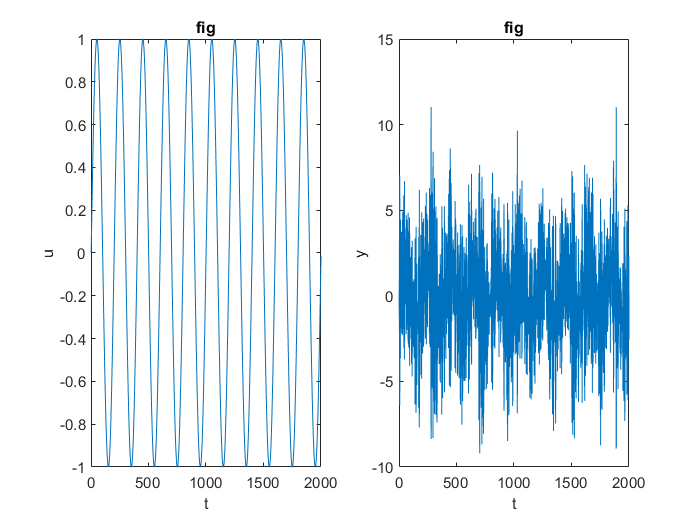

% nu = 100;
% previous_u = -100; 
% for mag=0:1:100
%     r = mag * ones(1,nu);
%     [u,y] = assignment_sys_36(r);
%     u(1)
%     previous_u
%     if (u(1) == previous_u)
%         fprintf("M is equal to %d", u(1));
%         break;
%     end
%     previous_u = u(1);
% end
% 
% % M is equal to 3

N = 2000;
f = 10;
offset = 0;
A = 1;

t = (0 : 1/N : 1)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1, 2, 1)
plot(u)
xlabel("t");
ylabel("u");
title("fig");

subplot(1, 2, 2)
plot(y)
xlabel("t");
ylabel("y");
title("fig");

% we now can know M is 3

## Part 2: Nonparametric identification

### 2.1 

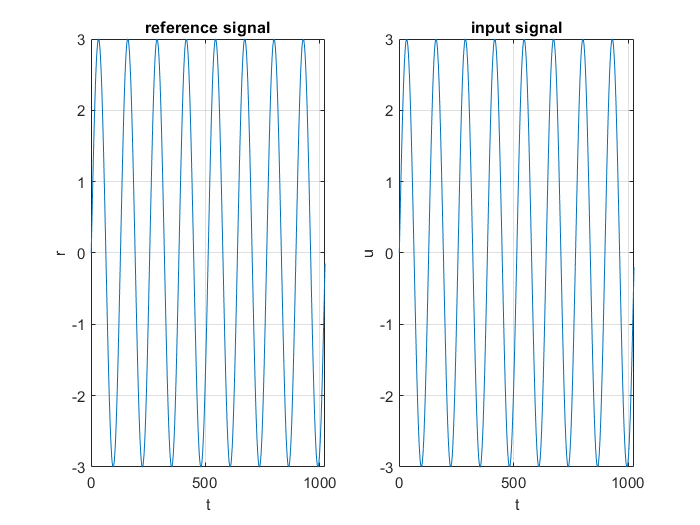

% period = 128;
% N = 1024;
% r = 3*sin( [0: 1: N-1] * pi / period )

% system setup
N = 1024;
Ts = 1;
n_freq = 128;


f = [0: 1: N-1]/n_freq/Ts;
r = 3 * sin(2*pi*f) + offset;

figure;
subplot(1, 2, 1)
plot(r)
grid on
xlabel("t"); ylabel("r"); title("reference signal");

[u,y] = assignment_sys_36(r);
subplot(1, 2, 2)
plot(u)
grid on
xlabel("t"); ylabel("u"); title("input signal");


figure;
G_ETFE = etfe(iddata(y,u))

G_ETFE =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 128 frequency points, ranging from 0.02454 rad/s to 3.142 rad/s.
 
Sample time: 1 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                  
Estimated using ETFE on time domain data.


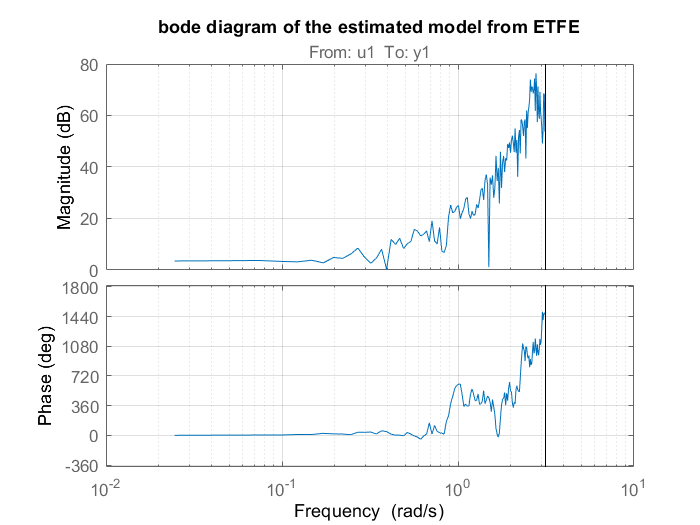

bode(G_ETFE)
grid on
title("bode diagram of the estimated model from ETFE");

### 2.3

period = 128;
N = 1024;
r = 0*sin( [0: 1: N-1] * pi / period )

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


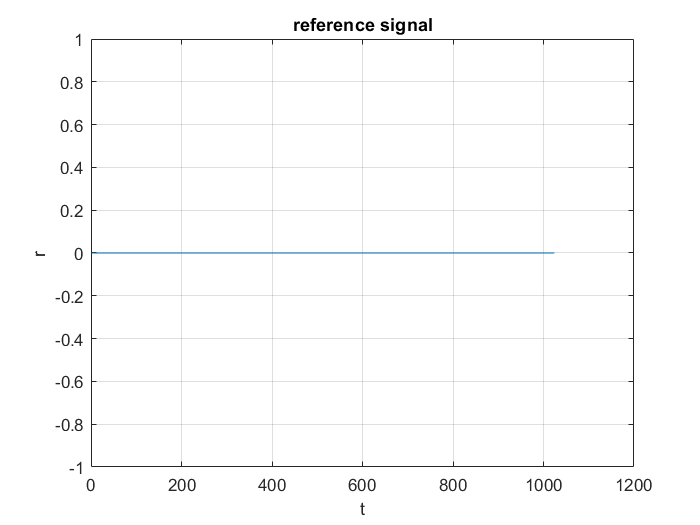

% r = 0 * sin(2*pi*f) + offset

figure;
plot(r)
grid on
xlabel("t"); ylabel("r"); title("reference signal");

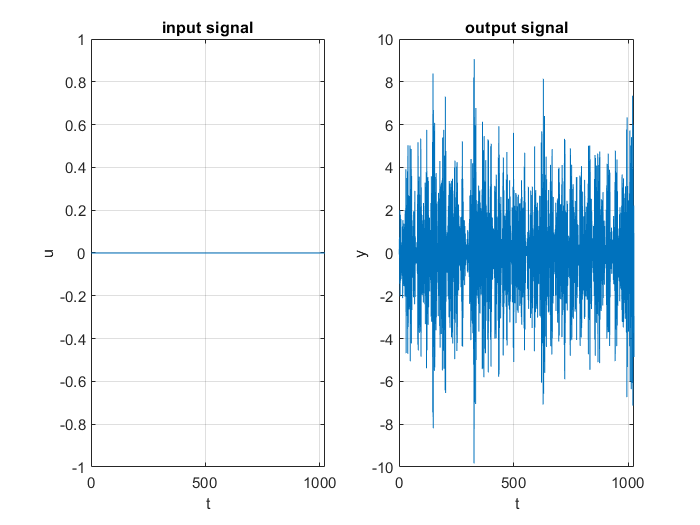


figure;
subplot(1, 2, 1)
[u,y] = assignment_sys_36(r);
plot(u)
grid on
xlabel("t"); ylabel("u"); title("input signal");

subplot(1, 2, 2)
plot(y)
grid on
xlabel("t"); ylabel("y"); title("output signal");

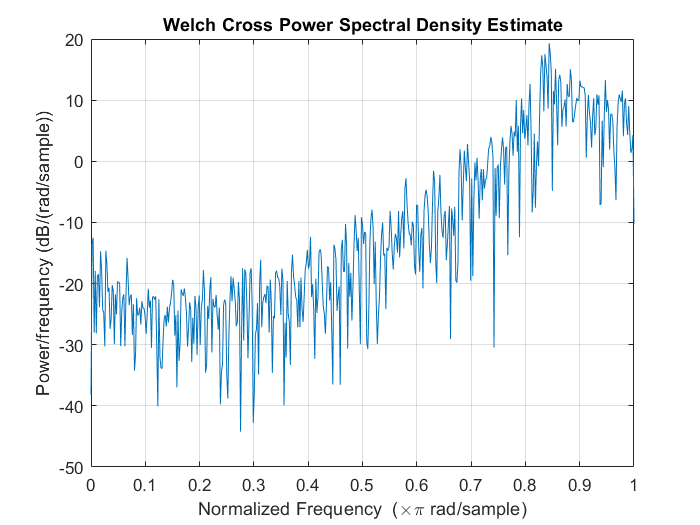


figure;
[Pv, W] = cpsd(y, y, 1024);
cpsd(y, y, 1024)

## Part 3: Expreiment Design

### 3.1

% prefer PRBS

### 3.2

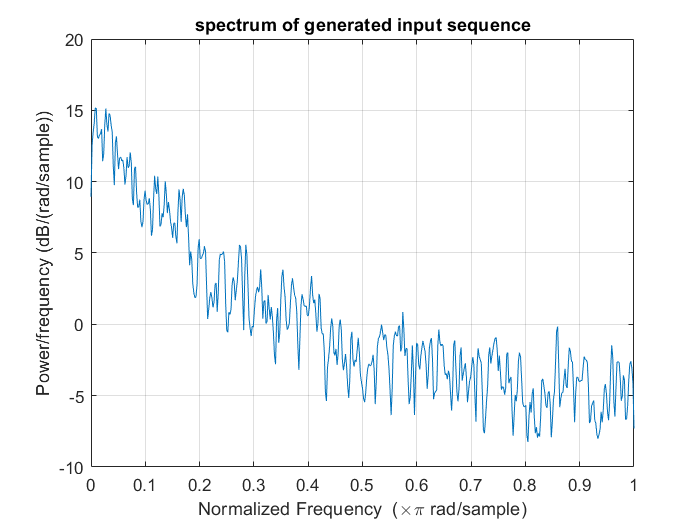

[r,P,w] = Generate_PRBS(0.9, 3000, 3, true);


% I think 0.83 is a good threshold


## Part 4: Parametric identification and validation

### 4.1 OE Model

% % Try OE Model
% 
% % divide the dataset into training set and validation set
% [r,P,w] = Generate_PRBS(0.83, 3000, 3, false);
% [u,y] = assignment_sys_36(r);
% train_ratio = 0.7;
% u_train = u([1: floor(train_ratio * length(u))]);
% y_train = y([1: floor(train_ratio * length(y))]);
% u_test = u([floor(train_ratio * length(u))+1: end]);
% y_test = y([floor(train_ratio * length(y))+1: end]);
% 
% % prepare loop for order selection
% order_upper = 20;
% nb = 0; nf = 0; nk = 0;
% 
% OE.order.order_points = [];
% OE.order.order_config = [];
% OE.order.error = [];
% 
% for order_sum = 1: 1: order_upper
%     
%     for nb = 0: 1: order_sum
%         
%         for nf = 0: 1: order_sum - nb
%             
%             nk = order_sum - nb - nf;
%             % for OE model, nk and nb cannot be zero at the same time
%             if nk == 0 && nb == 0
%                 continue;
%             end
%             
%             % identify a model
%             temp_sys = oe(iddata(y_train, u_train), [nb, nf, nk]);
%             % cost validate error
%             temp_predict_error = pe(temp_sys, iddata(y_test, u_test), 1);
%             temp_error = abs(8.5415-temp_predict_error.y' * temp_predict_error.y / length(y_test));
%             
%             % abort too abnormal result
%             if temp_error > 10
%                 continue;
%             end
%             
%             OE.order.order_points = [OE.order.order_points, order_sum];
%             OE.order.order_config = [OE.order.order_config, [nb; nf; nk]];
%             OE.order.error = [OE.order.error, temp_error];
%             
%         end
%                   
%     end
% end
% scatter(OE.order.order_points, OE.order.error);
% 

% [M, I] = min(OE.order.error);
% OE.model_configuration = OE.order.order_config(:, I);
% OE.model_order = OE.order.order_points(I);
% 

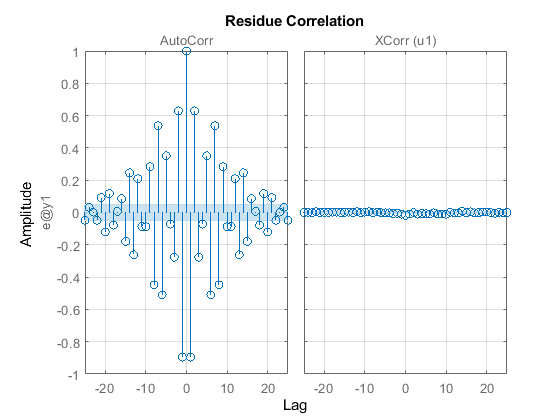

% OE.model_configuration

% OE.sys = oe(iddata(y_train, u_train), OE.model_configuration');
OE.sys = oe(iddata(y_train, u_train), [10,10,1]);

OE.resid = resid(iddata(y_train,u_train), OE.sys);
figure
resid(iddata(y,u), OE.sys)
grid on;

### 4.1 ARX Model

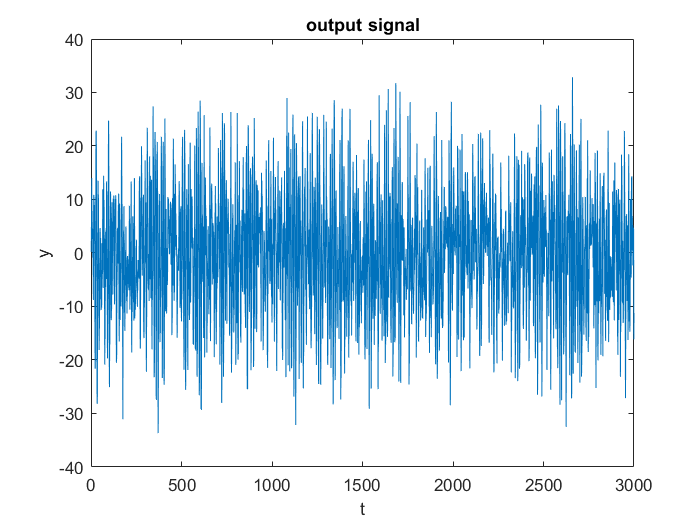

[r,P,w] = Generate_PRBS(0.83, 3000, 3, false);
[u,y] = assignment_sys_36(r);
figure;
plot(y)
xlabel("t"); ylabel("y"); title("output signal");

G_ARX = arx([y u], [10 10 1])

G_ARX =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                        
                                                                                                                           
  A(z) = 1 + 1.621 z^-1 + 1.164 z^-2 + 0.8434 z^-3 + 0.8442 z^-4 + 0.6673 z^-5 + 0.8478 z^-6 + 0.8822 z^-7 + 0.8142 z^-8   
                                                                                               + 0.7515 z^-9 + 0.3717 z^-10
                                                                                                                           
                                                                                                                           
  B(z) = 1.789 z^-1 + 4.935 z^-2 + 5.114 z^-3 + 2.499 z^-4 + 0.4261 z^-5 + 0.06353 z^-6 - 0.2413 z^-7 - 0.07477 z^-8       
                                                                                              + 0.08942 z^-9 + 0.1103 z^-10


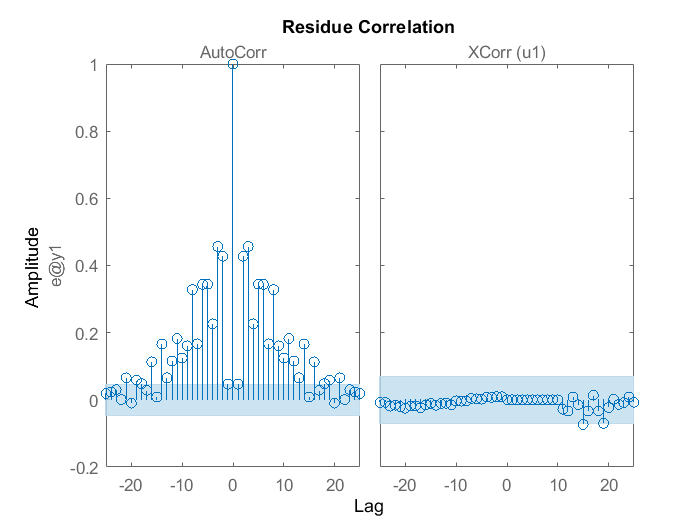

% good 10 9 1
resid([y u], G_ARX)




% Using the systemIdentification Toolbox 
% Using the r to generate u and y, then import these two time domian data
% into the Toolbox
% Using the polynomial model estimation with ARX model
% In the Polynomial Model screen

## Part 5: Experimental verification of variance estimates

### 5.1

% using the same r to generate the u and y, set the loop number as 100
Loop = 100;

[r,P,w] = Generate_PRBS(0.83, 3000, 3, false);

% using the parameter obtained from previous section
nb = 4; nf = 13; nk = 1;
result = zeros([Loop, nb+nk+nf-1], 'double');

for i = 1:Loop
    [u,y] = assignment_sys_36(r);
    G_OE = oe([y u], [nb nf nk]);
    F = G_OE.Structure.F.Value(2:1:end);
    B = G_OE.Structure.B.Value(2:1:end);
    result(i,:) = [B F];
end
clear B F i
% the storing fromat is B(1x4) and F(1x13) in one raw
result

result =     1.7233    2.0307    0.0446    0.1056   -0.0760    0.3409    0.1618    0.2902    0.0069    0.5922   -0.1584    0.4982   -0.0396    0.0279   -0.0748    0.0930   -0.0449
    1.7119    5.1854    5.4467    2.0274    1.7603    1.1749    0.6449    0.8866    0.6658    0.8667    0.9385    0.7597    0.7113    0.4320   -0.0876   -0.0131    0.0573
    1.7563    1.8102    0.3465    0.0502   -0.1479    0.5095    0.0195    0.3585    0.0122    0.5831   -0.2089    0.6513   -0.2504    0.2461   -0.2161    0.1499   -0.0571
    1.7669    2.2251   -0.0512   -1.3875    0.1102   -0.0676   -0.0126    0.3961   -0.2092    0.5649   -0.1574    0.2941   -0.0605   -0.0236   -0.2693    0.2149   -0.0796
    1.7726    1.8434    0.5232    0.1522   -0.1069    0.5240    0.1120    0.2398    0.2018    0.4312   -0.0662    0.6146   -0.2322    0.2858   -0.2374    0.1592   -0.0592
    1.7652    2.3646   -0.0712   -1.0218    0.1770   -0.1167    0.1884    0.2772   -0.1066    0.5669   -0.1117    0.2625    0.0812   -0.

### 5.2

% due to the existance of the noise, each realization is different from
% each other


### 5.3. Variance Comparison

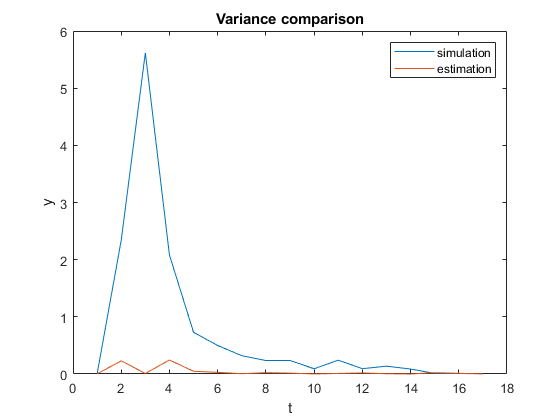

cov = getcov(G_OE);

cov_est = diag(cov)';

cov_sim = zeros([2, (nb+nk+nf-1)], 'double');
for k = 1:(nb+nk+nf-1)
     
    cov_sim(1, k) = mean(result(:, k));
    cov_sim(2, k) = var(result(:, k));
end

% figure;
% plot(result(:,k))
% xlabel("t"); ylabel("y"); title("output signal");


figure;
plot(cov_sim(2,:))
hold on
plot(cov_est)
legend('simulation','estimation')
xlabel("t"); ylabel("y"); title("Variance comparison");


clear k

### 5.4

result_54 = zeros([Loop, nb+nk+nf-1], 'double');

% for i = 1:Loop
%     [u,y] = assignment_sys_36(r);
%     G_OE = oe([y u], [nb nf nk]);
%     F_init = G_OE.Structure.F.Value;
%     B_init = G_OE.Structure.B.Value;
%     M_init = idpoly([], B_init, [], [], F_init);
%     M_oe = oe([y u], M_init);
%     F = G_OE.Structure.F.Value(2:1:end);
%     B = G_OE.Structure.B.Value(2:1:end);
%     result_54(i,:) = [B F];
% end

OEopt = oeOptions;
OEopt.SearchOptions.Tolerance = 0.0001;

for i = 1:Loop
    
    % Generate new data
    [u,y] = assignment_sys_36(r);
    
    % update starting point
    B_init = median(result_54([1: 1: i], [1: 1: nb]),1);
    F_init = median(result_54([1: 1: i], [nb+1: 1: end]),1);
    M_init = idpoly([], [1, B_init], [], [], [1, F_init]);
    
    % start OE model identification from the starting point
    M_oe = oe([y u], M_init,OEopt);
    
    % record the parameter
    F = G_OE.Structure.F.Value(2:1:end);
    B = G_OE.Structure.B.Value(2:1:end);
    result_54(i,:) = [B F];
           
end
    

clear B F i
% the storing fromat is B(1x4) and F(1x13) in one raw
result_54

result_54 =     1.7678    2.0702   -0.0826   -0.6943    0.0195    0.0388    0.2009    0.1670    0.0469    0.4585   -0.1159    0.3752   -0.0692    0.0051   -0.1833    0.1630   -0.0674
    1.7678    2.0702   -0.0826   -0.6943    0.0195    0.0388    0.2009    0.1670    0.0469    0.4585   -0.1159    0.3752   -0.0692    0.0051   -0.1833    0.1630   -0.0674
    1.7678    2.0702   -0.0826   -0.6943    0.0195    0.0388    0.2009    0.1670    0.0469    0.4585   -0.1159    0.3752   -0.0692    0.0051   -0.1833    0.1630   -0.0674
    1.7678    2.0702   -0.0826   -0.6943    0.0195    0.0388    0.2009    0.1670    0.0469    0.4585   -0.1159    0.3752   -0.0692    0.0051   -0.1833    0.1630   -0.0674
    1.7678    2.0702   -0.0826   -0.6943    0.0195    0.0388    0.2009    0.1670    0.0469    0.4585   -0.1159    0.3752   -0.0692    0.0051   -0.1833    0.1630   -0.0674
    1.7678    2.0702   -0.0826   -0.6943    0.0195    0.0388    0.2009    0.1670    0.0469    0.4585   -0.1159    0.3752   -0.0692   

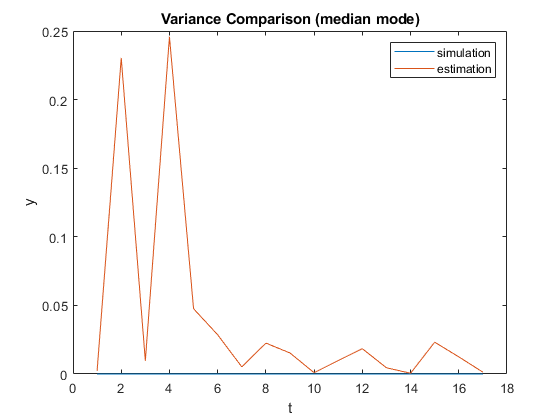

cov_sim_54 = zeros([2, (nb+nk+nf-1)], 'double');
for k = 1:(nb+nk+nf-1)
     
    cov_sim_54(1, k) = mean(result_54(:, k));
    cov_sim_54(2, k) = var(result_54(:, k));
end

% figure;
% plot(result_54(:,k))
% xlabel("t"); ylabel("y"); title("output signal");
% 

figure;
plot(cov_sim_54(2,:))
hold on
plot(cov_est)
legend('simulation','estimation')
xlabel("t"); ylabel("y"); title("Variance Comparison (median mode)");


clear k Loop

## Part 6: Estimation of a Box Jenkins model for minimum variance

### 6.1. Identify an BJ model

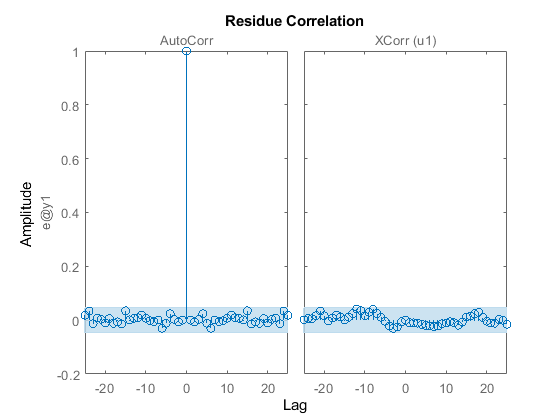

nb = 10;
nf = 10;
nc = 3;
nd = 5;
nk = 1;

BJ.sys = bj(iddata(y,u), [nb, nc, nd, nf, nk]);

resid(iddata(y,u), BJ.sys)

### 6.2. compute the variance

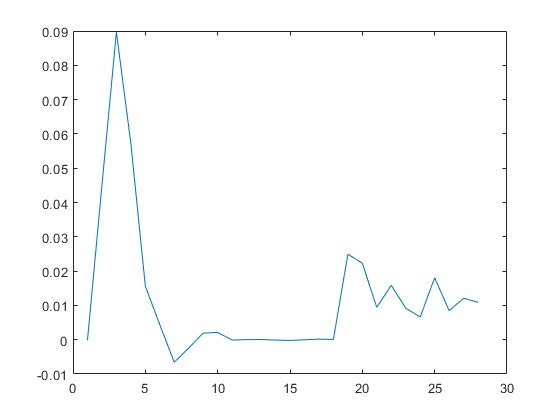

cov = getcov(BJ.sys);
figure 
plot(cov(2,:))

## Function Used

function [r,P,w] = Generate_PRBS(probability, N, mag, plt_flag)
%%%%%%%%%%%%%%%
%% generate PRBS based on:
%% u(t) = u(t-1) with probability p
%% u(t) = -u(t-1) with probability 1-p
%% and may plot spectral density based on setting
%% input: 
%%    P : prbability
%%    N : total input points
%%    mag: output magnitude
%%    plt_flg: if true, plot sepctral density
%% output:
%%    u : generated input sequence
%%    P : spectral density of P
%%    w : spectral density points
%%%%%%%%%%%%%%%%


    % determine the initial entry of u, that is u(1)
    if rand(1,1)>=0.5
        r(1) = mag;
    else
        r(1) = -mag;
    end
    
    % generate sequence
    for i = 2:1:N
        if rand(1,1) <= probability
            r(i) = r(i-1);
        else
            r(i) = -r(i-1);
        end
    end
    
    % get spectrum of generated input sequence
    [P,w] = cpsd(r,r,N);
    
    if (plt_flag == true)
        cpsd(r, r);
        title('spectrum of generated input sequence')
    end
    
end